Name: Mukesh Aryal

Student ID: 268456

f = @(x,y) (x-2).^2 + (y-1).^2;

fcon = @(x) deal(x(1).^2-x(2), x(1)+x(2).^2);

options = optimset('Display','iter')

options = struct with fields:
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
     


[xmin3,fmin3,flag,output] = fmincon(@(x) f(x(1),x(2)),[0 0],[],[],...
    [],[],[],[],fcon,options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.000000e+00    0.000e+00    2.000e+00
    1       6    4.404959e+00    1.322e-01    1.631e+00    3.636e-01
    2       9    4.727773e+00    1.911e-02    6.213e-02    1.418e-01
    3      12    4.799026e+00    6.329e-04    7.387e-03    2.633e-02
    4      15    4.801519e+00    8.198e-06    1.435e-03    2.909e-03
    5      18    4.801550e+00    1.732e-07    7.768e-05    4.445e-04
    6      21    4.801551e+00    1.013e-13    1.000e-05    4.439e-07
    7      24    4.801551e+00    2.309e-11    2.673e-06    5.157e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


xmin3 =    -0.0388    0.1969


fmin3 = 4.8016

flag = 1

output = struct with fields:
         iterations: 7
          funcCount: 24
    constrviolation: 2.3091e-11
           stepsize: 5.1567e-06
          algorithm: 'interior-point'
      firstorderopt: 2.6727e-06
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 6.554697e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 2.309083e-11, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   6.55e-07       OptimalityTolerance =   1e-06 (default)↵r

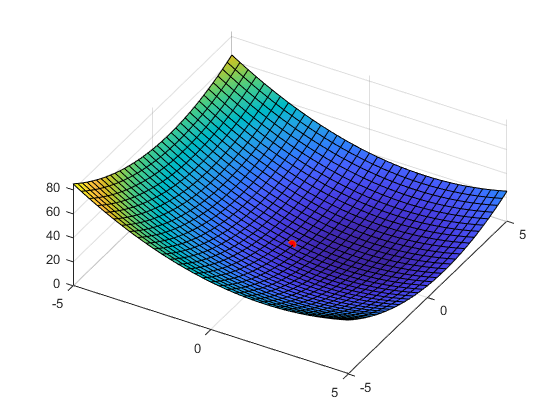

fsurf(f);
hold on;
plot3(xmin3(1),xmin3(2),fmin3,'o','MarkerFaceColor','r');
view(30,60);